%Simulation
amax = 110;
g = -9.81;
dt = 0.01;
t = linspace(0,15,15/dt);
A = [1 dt 0.5*dt^2; 0 1 dt; 0 0 1];
x = zeros(3,length(t));
prev_x = zeros(3,length(t));
a_sim = (0 + (amax - 0)/0.8*t).*(t>0 & t<=0.8)+amax.*(t>0.8 & t <= 0.9)+(amax + (g - amax)/0.1*(t-0.9)).*(t>0.9 & t<1)+g.*(t>=1);

for i = 1:length(t)-1
    prev_x(3,i) = a_sim(i);
    x(:,i) = A*prev_x(:,i);
    prev_x(1,i+1) = x(1,i);
    prev_x(2,i+1) = x(2,i);
    if x(1,i)<0
        break
    end
end

s_n = x(1,:)+(5.985.*randn(1,length(t)));
v_n = x(2,:)+(2.*randn(1,length(t)));
a_n = x(3,:)+(0.0346.*randn(1,length(t)));

%Measurement begins
H = [1 0 0; 0 0 1];
R = [0.17^2 0; 0 0.0784^2];
Q = [0 0 0; 0 0 0; 0 0 1];
P = eye(3);


K = [0 0; 0 0; 0 0]

K =      0     0
     0     0
     0     0



alt=s_n

alt =    -2.5336   -2.6481   -6.7114    6.4017   -1.3868    6.0696  -12.9161    0.0843   -2.3920   10.8770    2.5946    3.4919    3.7116    8.8725   -1.1974    8.9993    4.8262    1.0016   -0.2036    5.1395    7.4489    5.9965    2.8396    2.8348   -4.0198    9.6464   -3.4144    2.2862   -2.6957  -15.0888    3.6599   -8.8355    4.0672    2.7758   -9.3108    2.4846    9.0020   -3.4833   -4.9719   -9.0911   -1.5462    2.8066    8.2600   -2.6430    3.1702    1.9517    2.1265   -4.8809    0.1871    2.2204


acc=a_n

acc =     0.0119    1.3822    2.7925    4.0700    5.4812    6.8121    8.2831    9.5904   11.0737   12.3729   13.7510   15.1539   16.5809   17.8554   19.2379   20.6420   21.9950   23.3328   24.8036   26.1319   27.5000   28.8815   30.2662   31.6131   32.9734   34.4695   35.7948   37.1553   38.5618   39.8899   41.2666   42.6444   44.0496   45.3923   46.7656   48.1810   49.5574   50.9197   52.2584   53.6584   55.0012   56.3973   57.7699   59.2484   60.5614   61.9379   63.3313   64.6633   66.0376   67.3557


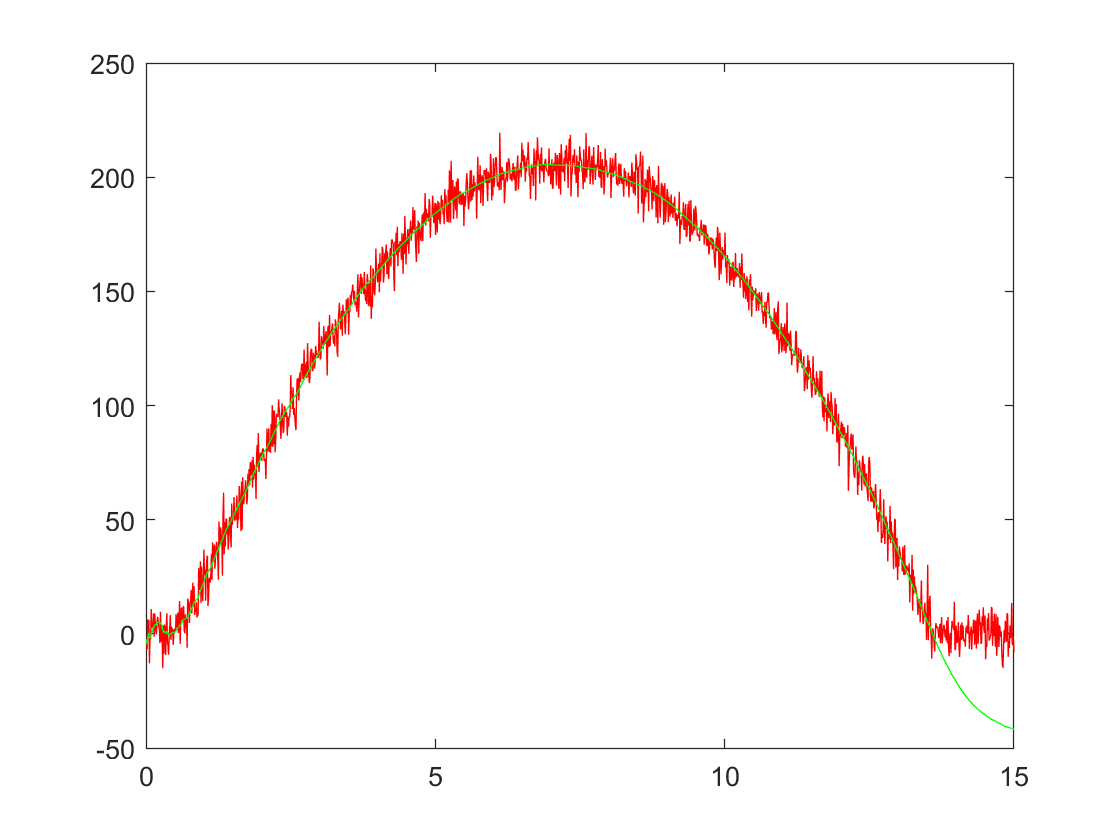


estimate = zeros(3,length(t));
estimate(:,1) = [alt(1); 0; acc(1)];
for i = 2:length(t)
    K = P*H'*inv(H*P*H' + R);
    P = (eye(3) - K*H) *P;
    P = A*P*A' + Q;
    estimate(:,i) = A*estimate(:,i-1);
    estimate(:,i) = estimate(:,i) + K*([alt(i);acc(i)] - H*estimate(:,i));

end

plot(t,s_n,'r');
hold on
plot(t,estimate(1,:),'g')